Workflow Oxcart mass spectrum calibration

mc = tof2mcSimple(pos.tof,0,pos.VDC,pos.detx,pos.dety,110);

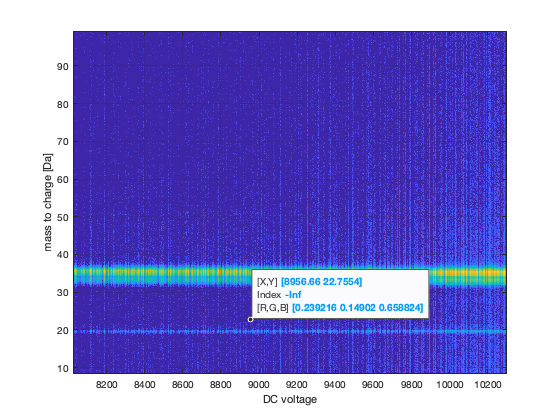



%plotting data history
historyFig = figure("Name","mc experiment history");
historyAx = axes(historyFig);
MAXMC = 100; %maximum mc that makes sense
HISTORYPIX = 1024; %number of pixels in the hit sequence tof image
TOFPIX = 512; % number of vertical pixels for tof image

numAtom = length(mc);

mcTmp = mc(mc<MAXMC);
VDCtmp = pos.VDC(mc<MAXMC);

%[mcImage, tofImageCenters] = hist3([(1:length(mcTmp))', mcTmp],[HISTORYPIX,TOFPIX]);
[mcImage, tofImageCenters] = hist3([VDCtmp, mcTmp],[HISTORYPIX,TOFPIX]);
mcImage = mcImage';
mcImage = log(mcImage); % if weak peaks are to be imaged
im = imagesc(mcImage,'XData',tofImageCenters{1},'YData',tofImageCenters{2});
historyAx.YDir = "normal";

% plotting voltage history
%yyaxis right
%p = plot(pos.VDC,'r');
%p.LineWidth = 2;
%ylabel 'DC voltage [V]'

% image formatting
%yyaxis left
ylabel 'mass to charge [Da]'
xlabel 'DC voltage'
grid on

peak tracking vs voltage - simple voltage correction

fitPeak = [18, 23] % peaks as beginning/end

fitPeak =     18    23


ionsPerFitSegment = 1000000;

numMcBins = floor(numAtom/ionsPerFitSegment);
binLimitsIdx = round(linspace(1,numAtom,numMcBins+1));
binCenters = round((binLimitsIdx(2:end) + binLimitsIdx(1:end-1))/2);
pkLoc = [];

for i = 1:numMcBins
    limits(i,:) = [pos.VDC(binLimitsIdx(i)), pos.VDC(binLimitsIdx(i+1))];
    mcBin = mc(pos.VDC > pos.VDC(binLimitsIdx(i)) & pos.VDC < pos.VDC(binLimitsIdx(i+1)));
    mcBin = mcBin(mcBin>fitPeak(1) & mcBin<fitPeak(2));
    pkLoc(i) = median(mcBin);
    VDC(i,1) = mean(pos.VDC(pos.VDC > pos.VDC(binLimitsIdx(i)) & pos.VDC < pos.VDC(binLimitsIdx(i+1))));
    
end
figure;
title 'peak location vs DC voltage'
corr = pkLoc/pkLoc(1);
scatter(VDC', corr)
hold on
xlabel 'DC voltage'
ylabel 'correction factor'

[xData, yData] = prepareCurveData( VDC', corr );
% Set up fittype and options.
ft = fittype( 'poly2' );
% Fit model to data.
fitresult = fit( xData, yData, ft );

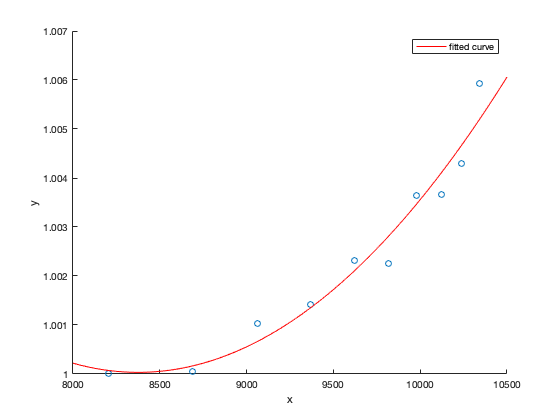

plot(fitresult);

%
%corrFac = interp1(binCenters,corr,1:length(mc),'linear','extrap')';
corrFac = fitresult(pos.VDC);
mc2 = mc ./ corrFac;

clear corr corrFac

single bowl fit

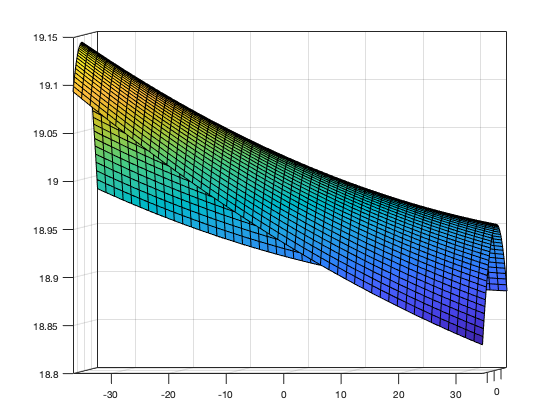

%bowl fit on full data
%in = mc>fitPeaks(2,1) & mc<fitPeaks(2,2);
mcIdeal = 18.667;
in = mc2>18 & mc2<22;
detxIn = pos.detx(in);
detyIn = pos.dety(in);
mcIn = mc2(in);

[xData, yData, zData] = prepareSurfaceData( detxIn, detyIn, mcIn );
ft = fittype( 'poly22' );
[bowlFit, gof] = fit( [xData, yData], zData, ft );

figure( 'Name', 'Bowl fit 1' );
h = plot(bowlFit);


corr = bowlFit(pos.detx,pos.dety)/mcIdeal;

mc3 = mc ./ corr;

linear correction 

peakLocIs = [1.95,14.55,26.9];
peakLocIdeal = [1,13.5,27];

corrRatio = peakLocIdeal./peakLocIs;

mc4 = mc3 .* interp1(peakLocIs',corrRatio',mc3,'linear','extrap');


iterative fitting of peak to voltage curve 